clear 
clc

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 10E6;                     % sample rate
wt = [101, 249, 499] / 1024;     
Fin = wt .* Fs;                 % input frequency (Hz)
Ron0 = 6.5;                     % On-Resistance (ohm)
L = [0.2, 0.4, 0.6,0.8, 1, 2, 3];
alpha = [-1.15, -0.15, 0.15, 0.3, 0.4, 0.6, 0.68];
VTH = 0.457;

getHD_new(Ron0*(1.8-VTH)/(db2mag(-1.1)-VTH), V0, C1, Fin(3), alpha(1))

ans =   -78.9812  -81.0674


%SD Exchange effect


Cb = 5;
Cp1 = 2;
Cp2 = 0;
Cp3 = 1;

Ctot = Cb + Cp1 + Cp2 + Cp3;
% Vgs0 = [Cb * 1.8 - (Cp1 + Cp2)*0.9 - Cp3 * 0.18] / Ctot
Vgs1 = V0* Cp1/Ctot;
mag2db(Vgs1)

ans = -13.0047

Vgs0 = (Cb * 1.8 - (Cp1 + Cp2)*0.9 - Cp3 * 0.18) / Ctot

Vgs0 = 0.8775

KV = Vgs1 / (Vgs0-VTH);
% Vgs0 = db2mag(0.293)
mag2db(Vgs0)

ans = -1.1351

% Vgs0 = db2mag(0.71)
Ron = 1/((Vgs0-VTH)*(280E-6 * 32 * 3 / 0.2))

Ron = 17.6944

% Ron = db2mag(7.5)
mag2db(Ron)

ans = 24.9567

getHD_new(Ron, V0, C1, Fin(3), alpha(1))

ans =   -81.5927  -83.6682



R2 = (KV^2 + KV^4)* Ron / 2

R2 = 3.2142


R1 = (Vgs1/(Vgs0-VTH)) * Ron;
mag2db(R1)

ans = 19.4766

mag2db(R2)

ans = 10.1414

mag2db(R2*C1*Fin(3)*pi*V0)

ans = -55.3644

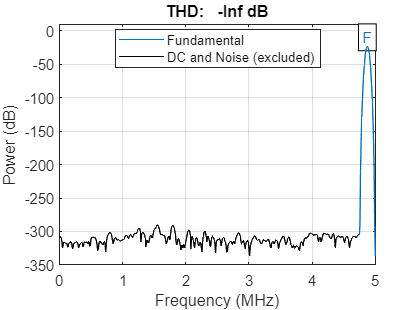

ans = -Inf

t = 0:1/Fs:1/Fs*1023;
omega = 2*pi*Fin(3);
Vgs = Vgs0 + Vgs1*sin(omega*t);
thd(Vgs, Fs)

ron_o = 1./((Vgs - VTH).*(280E-6 * 32 * 3/0.2));


ron = db2mag(27) + db2mag(19.8)*sqrt(2)*sin(omega*t) - db2mag(5.21)*sqrt(2)*sin(2*omega*t) +...
    db2mag(-8.97)*sqrt(2)*sin(3*omega*t)

ron =    22.3872   24.0171   20.7680   27.1807   19.1752   30.0669   17.6300   32.5253   16.1459   34.4516   14.7286   35.7948   13.3795   36.5571   12.1027   36.7861   10.9129   36.5603    9.8427   35.9737    8.9469   35.1196    8.3019   34.0780    7.9993   32.9080    8.1339   31.6463    8.7888   30.3106   10.0186   28.9063   11.8350   27.4349   14.1976   25.9007   17.0120   24.3155   20.1356   22.6994   23.3918   21.0781   26.5886   19.4783   29.5410   17.9227   32.0914   16.4262   34.1256   14.9959


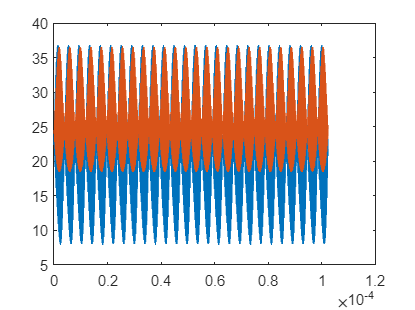

plot(t,ron, t, ron_o)

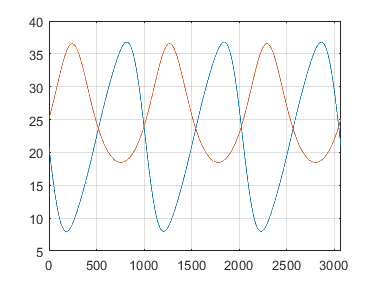

T_ron = PhaseOrder(ron, Fin(end), Fs);
T_ron_o = PhaseOrder(ron_o, Fin(end), Fs);
figure
plot(repmat(T_ron.Value,3,1));
hold on;
plot(repmat(T_ron_o.Value,3,1));
hold off;
grid on; box on

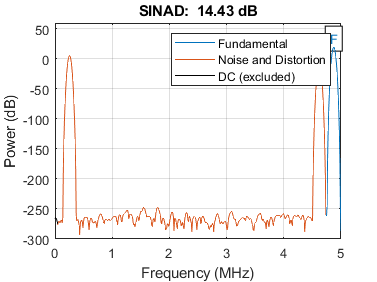

ans = 14.4272

sinad(ron,Fs)

[~, harmpower, harmfreq]= thd(repmat(ron,1,4),Fs, 5, 'aliased')

harmpower =    19.8000
    5.2100
   -8.9700
 -264.1749
 -265.0334


harmfreq = 1.0e+06 *

    4.8730
    0.2539
    4.6191
    0.5059
    4.3641


harmpower(2) - harmpower(1)

ans = -14.5900

harmpower(3) - harmpower(1)

ans = -28.7700